# Homework 8 (Solutions)

Math 3607, Autumn 2021

Tae Eun Kim

clear

## Problem 1 (Image compression)

First, load and save the image as a matrix.

A = imread('hubble_gray.jpg');
% imshow(A)

To do maths (i.e., SVD), we first need to convert $A$ into a double matrix. Otherwise, MATLAB will complain. For later use, we store the dimensions of $A$ as $m$ (number of rows) and $n$ (number of columns), and all factors of SVD using the usual variables.

A = double(A);
[m,n] = size(A);
[U,S,V] = svd(A);
sigma = diag(S); % for convenience

(a) Singular values

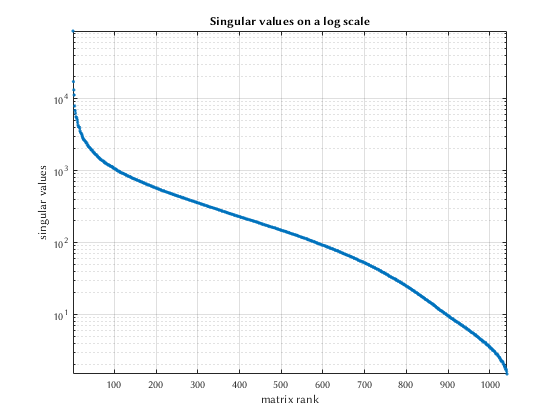

clf
semilogy(sigma, '.')
title('Singular values on a log scale')
xlabel('matrix rank')
ylabel('singular values')
axis tight, grid on

(b) Accumulation of singular values

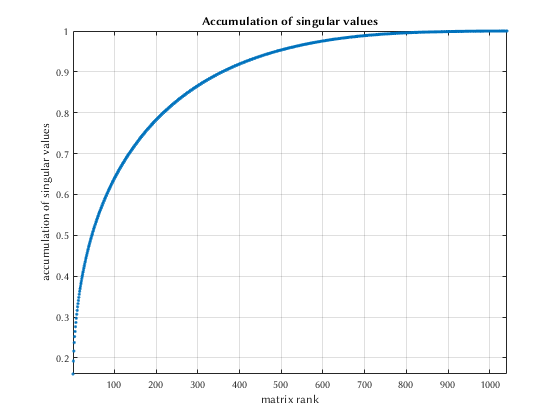

clf
plot(cumsum(sigma)/sum(sigma), '.')
title('Accumulation of singular values')
xlabel('matrix rank')
ylabel('accumulation of singular values')
axis tight, grid on

(c) Low-rank, compressed images.

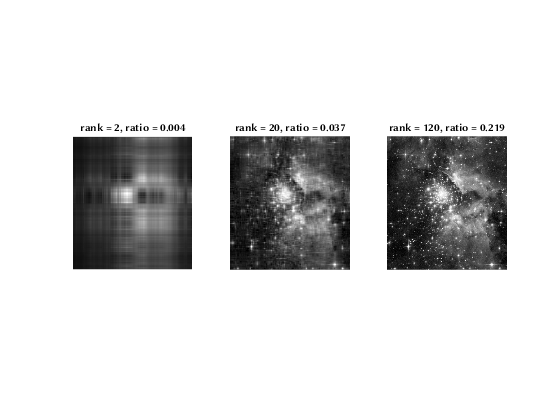

clf
j = 0;
for k = [2 20 120]
  j = j+1;
  subplot(1,3,j);
  Ak = U(:,1:k)*S(1:k,1:k)*V(:,1:k)';
  imshow(Ak, [0 255]);
  comp_ratio = k*(m+n+1)/(m*n);
  title(sprintf('rank = %d, ratio = %5.3f', k, comp_ratio), 'FontSize', 30)
end

## Problem 2 (Annuity with `FZERO`; FNC 4.1.4)

Let's write a script solving the problem for a single $P$ value:

P = 500;
n = 300;
FV = 1e6;  % value at maturity

We need to find an interest rate $r$ which satisfies

$\displaystyle \frac{12P}{r} \left( \left( 1 + \frac{r}{12} \right)^n - 1 \right) = 1,000,000$.

In other words, $r$ is a root of 

$\displaystyle f( r ) = \frac{12P}{r} \left( \left( 1 + \frac{r}{12} \right)^n - 1 \right) - 1,000,000$.

f = @(r) 12*P/r*( (1+r/12)^n - 1 ) - FV; % objective function
r = fzero(f, 0.01)                       % use 0.01 as an initial guess 

r =      1.235118070470635e-01

Now we carry out the same computation for $P = 500, 550, ... 1000$, while all other parameters are fixed.

n = 300;
FV = 1e6;
P = 500:50:1000;
for j = 1:length(P)
    f = @(r) 12*P(j)/r*( (1+r/12)^n - 1 ) - FV;
    r = fzero(f, 0.01);
    if j == 1
        fprintf(' %4s %8s\n', 'P', 'r')
        fprintf(' %13s\n', repmat('-', 1, 13))
    end
    fprintf(' %4d %8.4f\n', P(j), r)
end

    P        r


 -------------


  500   0.1235
  550   0.1181
  600   0.1132
  650   0.1086
  700   0.1043
  750   0.1003
  800   0.0965
  850   0.0929
  900   0.0895
  950   0.0862
 1000   0.0831


## Problem 3 (Lambert's W function; FNC 4.1.6)

Since $y = W(x)$ iff $x = y e^y$, $y$ is a root of $f(y) = x - ye^y$ for a given $x$, which can be found using `fzero` as follows:

Thus we can write a MATLAB function which computes $W(x)$ by

Note that the function can take an array input `x` and produce corresponding values in an array `y` of the same dimensions as `x`. So we can use this function just as any other built-in mathematical functions, say to plot its graph:

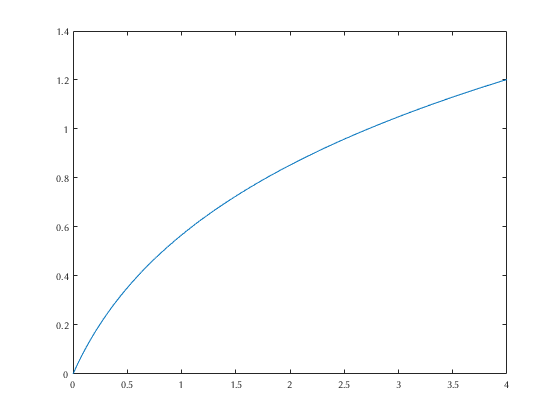

x = linspace(0, 4, 100);
clf
plot(x, lambertW(x))

**Note.** MATLAB actually comes with this function; it is named `lambertw`. Let's compare:

norm( lambertW(x) - lambertw(x) )

ans =      7.398305820894757e-16

This confirms that our code works very nicely!

Under the hood, MATLAB's `lambertw` uses a very fast rootfinding algorithm called *Halley's method*, which exhibits the cubic convergence! Unlike Newton or secant method which uses a linear model, Halley uses a $\text{Pad\'{e}}$ approximation (linear-over-linear rational function) to generate iterates. Take a look at the source code by:

type lambertw.m

## Problem 4 (Fixed-point iterations; adapted from FNC 4.2.1 and 4.2.2)

(a) For easy distinction, I will denote the three functions by $g_1, g_2$, and $g_3$. We confirm that the given $r$ is a fixed point by showing $g(r) = r$.

- $g_1(3) = \frac{1}{2} \left( 3 + \frac{9}{3} \right) = 3$.

- $g_2(\pi) = \pi + \frac{1}{4} \sin (\pi) = \pi$.

- $g_3(\pi) = \pi + 1 - \tan(\pi/4) = \pi + 1 - 1 = \pi$.

Fixed point iteration converges when $\vert g_j'(r) \vert < 1$.

- $g_1'(x) = \frac{1}{2} \left( 1 - \frac{9}{x^2} \right)$ $\Longrightarrow$ $g_1'(3) = 0$ (converge)

- $g_2'(x) = \frac{1}{4} \cos(x) \;  \Longrightarrow \; g_2'(\pi) = -\frac{1}{4}$ (converge)

- $g_3'(x) = 1 - \frac{1}{4} \sec^2(x/4) \; \Longrightarrow \; g_3'(\pi) = 1 - \frac{1}{2} = \frac{1}{2}$ (converge)

(b) Begin by defining $g_j$ as anonymous functions 

g1 = @(x) (x + 9/x)/2;
g2 = @(x) pi + sin(x)/4;
g3 = @(x) x + 1 - tan(x/4);

and the noted fixed points:

r1 = 3;
r2 = pi;
r3 = pi;

Inspired by the function `fpi` from Lecture 17 and the examples from the accompanying live script, we write the following helper function:

(This function is also included at the end of this file.)

Let's study the sequence $x_0, x_1, \ldots, x_{14}$ generated by $x_{k+1} = g_1(x_k)$:

format long e
n = 15;
x = myfpi(g1, 1.7, n)

x =      1.700000000000000e+00
     3.497058823529412e+00
     3.035325038341661e+00
     3.000205555964860e+00
     3.000000007041726e+00
     3.000000000000000e+00
     3.000000000000000e+00
     3.000000000000000e+00
     3.000000000000000e+00
     3.000000000000000e+00


This looks good. Let's analyze the errors.

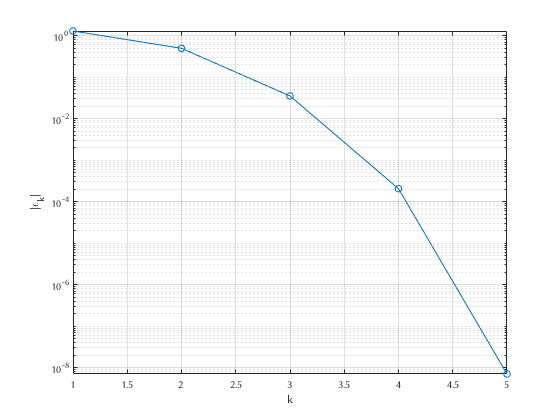

err = abs(x - r1);
clf
semilogy(err, 'o-'), axis tight, grid on
xlabel('k'), ylabel('|\epsilon_k|')

Wait, this is faster than linear convergence? Yes, but for a good reason. We discovered in the previous part that $g_1'(3) = 0$ which, according to the FPI convergence theorem, implies that

$\lim_{k \to \infty} \frac{ \vert \epsilon_{k+1} \vert }{ \vert \epsilon_{k} \vert } = \vert g'(3) \vert = 0$, superlinear convergence!

Unfortunately, this is difficult to confirm as the denominator quickly underflows (to zero):

err(2:end) ./ err(1:end-1)

ans =      3.823529411764706e-01
     7.106812447434803e-02
     5.818987735329192e-03
     3.425697871600165e-05
                         0
                       NaN
                       NaN
                       NaN
                       NaN
                       NaN


Moving onto $g_2$:

format long e
n = 15;
x = myfpi(g2, 1.7, n)

x =      1.700000000000000e+00
     3.389508856202910e+00
     3.080246551988983e+00
     3.156919561362624e+00
     3.137761076665939e+00
     3.142550545476954e+00
     3.141353180654625e+00
     3.141652521823013e+00
     3.141577686531497e+00
     3.141596395354367e+00


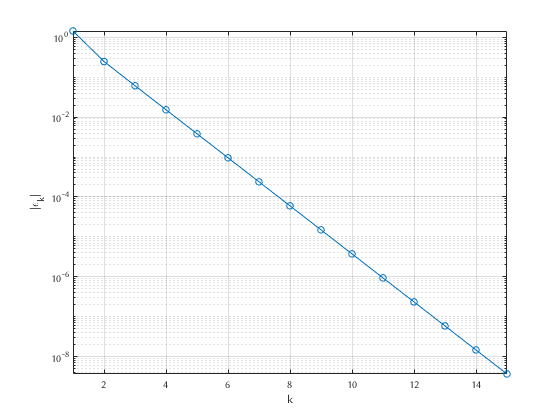

err = abs(x - r2);
clf
semilogy(err, 'o-'), axis tight, grid on
xlabel('k'), ylabel('|\epsilon_k|')

In this case, we see that the errors draw a nice straight line on the log-linear graph. Furthermore, the ratios of errors converge beautifully to the expected $\sigma = \vert g_2'(\pi) \vert = 1/4$:

err(2:end) ./ err(1:end-1)

ans =      1.719738249191035e-01
     2.474469234128392e-01
     2.498432234955372e-01
     2.499902120273960e-01
     2.499993882928684e-01
     2.499999617684353e-01
     2.499999976100850e-01
     2.499999998479356e-01
     2.499999999851645e-01
     2.499999999406578e-01


Lastly for $g_3$:

format long e
n = 15;
x = myfpi(g3, 1.7, n)

x =      1.700000000000000e+00
     2.247416847573013e+00
     2.617881264257347e+00
     2.850599005225683e+00
     2.986452451970267e+00
     3.061162389406461e+00
     3.100590041247924e+00
     3.120884031572326e+00
     3.131185104358556e+00
     3.136375386158261e+00


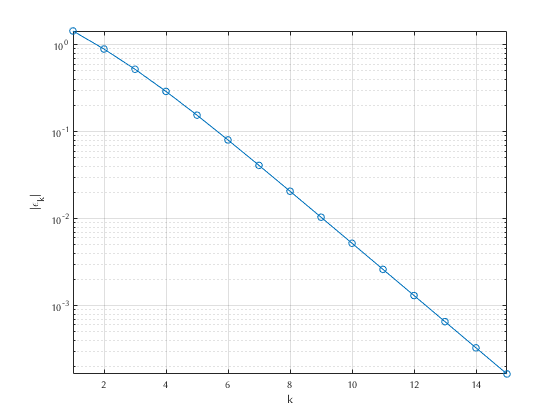

err = abs(x - r3);
clf
semilogy(err, 'o-'), axis tight, grid on
xlabel('k'), ylabel('|\epsilon_k|')

We also see that the errors draw a nice straight line on the log-linear graph. Furthermore, the ratios of errors converge beautifully to the expected $\sigma = \vert g_3'(\pi) \vert = 1/2$:

err(7:end) ./ err(6:end-1)

ans =      5.097908450034160e-01
     5.050561619051057e-01
     5.025708240006618e-01
     5.012964450721191e-01
     5.006510261133111e-01
     5.003262197391994e-01
     5.001632872715480e-01
     5.000816880784664e-01
     5.000408551610744e-01


Note that convergence is not as fast as in the previous case (even though both converge linearly) because the convergence rate $\sigma = 1/2$ for this case is larger than the previous one.

## Problem 5 (Convergence of Newton's method)

(a) A Calculus 1 exercise shows that

$f'(x) = \frac{1}{2\sqrt{|x|}}$, for all $x \in \mathbb{R}\setminus\{0\}$.

One Newton iteration takes any nonzero initial iterate $x_0 \neq 0$ to

$x_1 = x_0 - \frac{f(x_0)}{f'(x_0)} = x_0 - 2\text{sign}(x_0) |x_0| = -x_0$, regardless of the sign of $x_0$.

If you are unsure, examine two cases, $x_0 > 0$ and $x_0 < 0$, separately. Repeating the same computation with $x_0$ replaced by $-x_0$, we find that

$x_2 = x_1 - \frac{f(x_1)}{f'(x_1)} = -x_0 - 2\text{sign}(-x_0) |-x_0| = x_0$.

Back to the starting point! This means that the iterates generated by the Newton's iteration formula will just rock back and forth between $x_0$ and $-x_0$:


$$x_0, -x_0, x_0, -x_0, \ldots$$


a hopeless divergence scenario.

The following (minimal) Newton iteration code confirms our prediction.

f = @(x) sign(x).*sqrt(abs(x));
fprime = @(x) 1./(2*sqrt(abs(x)));
x = 1;
for k = 1:10
    x = x - f(x)/fprime(x)
end

x =     -1

x =      1

x =     -1

x =      1

x =     -1

x =      1

x =     -1

x =      1

x =     -1

x =      1

**Ponder.** Why do you think it is happening? Is it violating the convergence theorem for Newton's method?

(b)

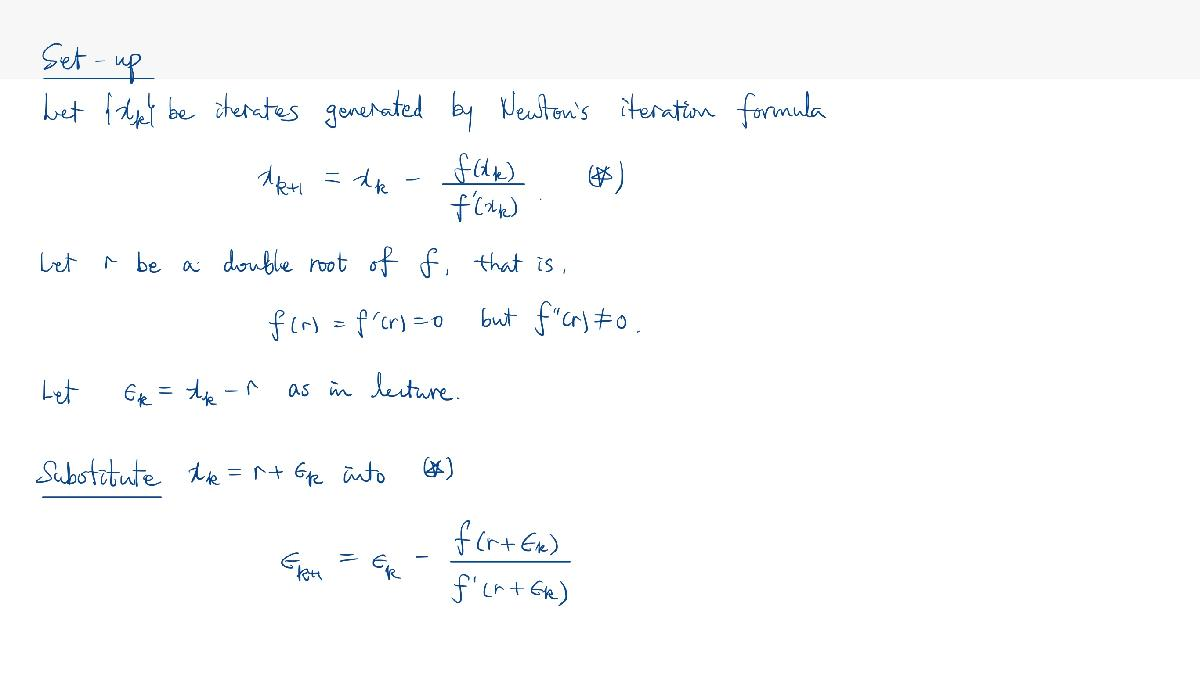

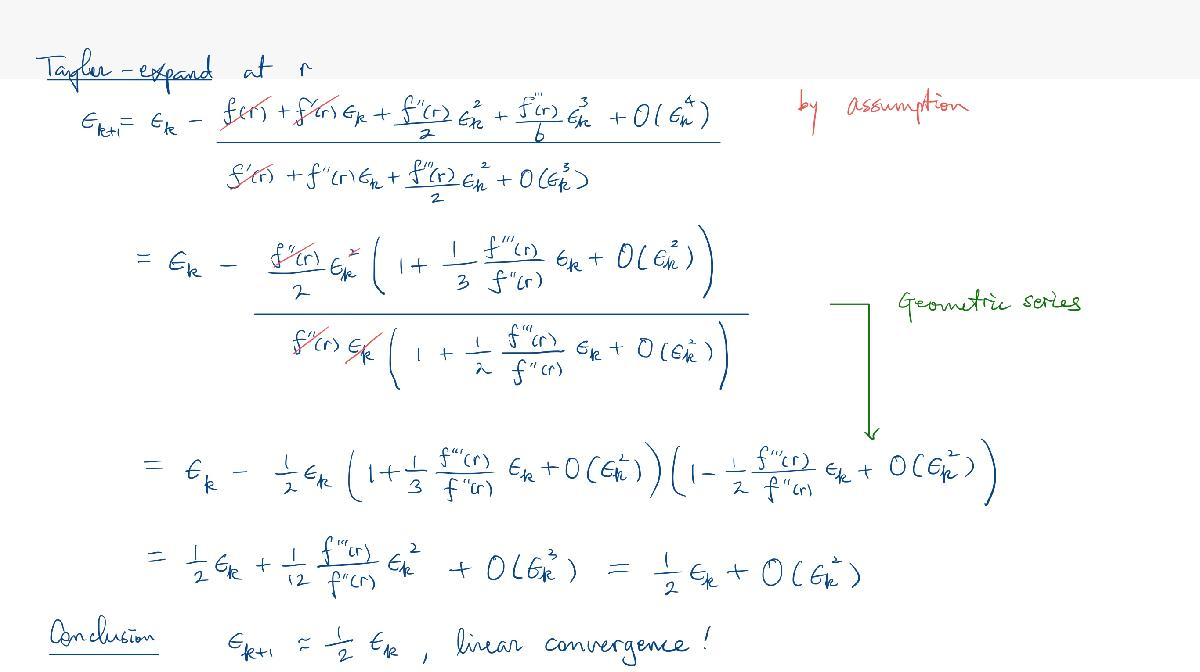

## Functions Used

### Lambert's W function

function y = lambertW(x)
% LAMBERT y = lambertW(x)
% Evaluate Lambert's W function y = W(x)
% by solving x = y*exp(y).
% 
% Input:
%   x    an array input
% Output:
%   y    W(x)
    y = zeros(size(x));
    for j = 1:numel(x)
        y(j) = fzero( @(y) x(j) - y*exp(y), 1 );
    end
end

### Fixed Point Iteration

function x = myfpi(g, x0, n)
% Generates fixed point iterates x_0, x_1, ..., x_{n-1}.
% All iterates are stored in a single (column) vector x.
    x = zeros(n, 1);
    x(1) = x0;
    for k = 1:n-1
        x(k+1) = g(x(k));
    end
end